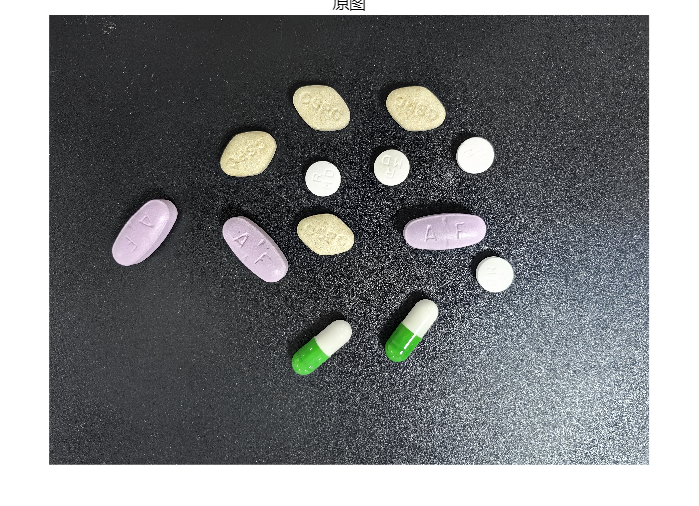


% 读取图像
I = imread("C:\Users\27492\Desktop\IMG\演示作业\药片1.jpg");
imshow(I);title("原图")

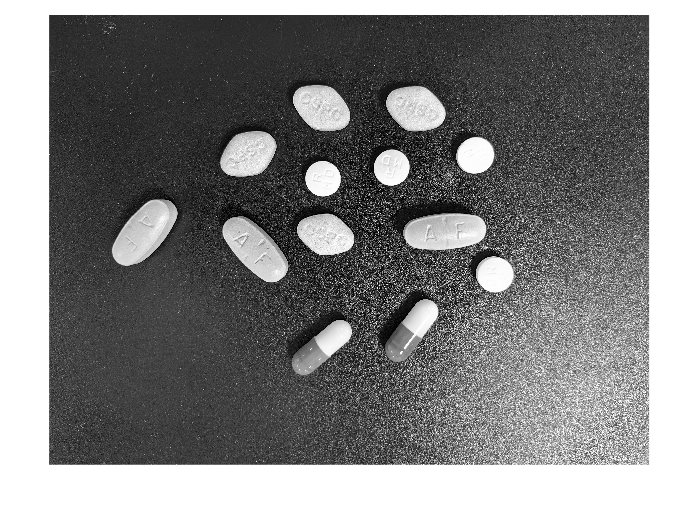

%将图片转化为灰度图
I1 = rgb2gray(I);
imshow(I1);

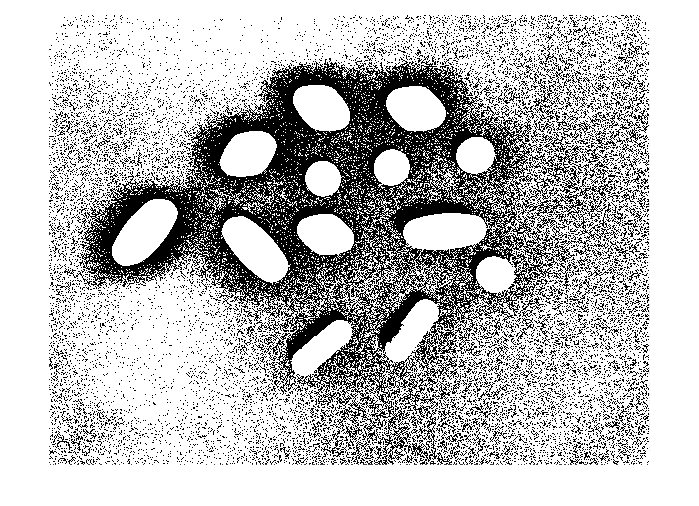

%用自适应阈值分割处理图像（处理图片光照不均匀）
T= adaptthresh(I1,0.4,'ForegroundPolarity', 'dark');
%imshow(T);
BW=imbinarize(I1,T);%将图像二值化
imshow(BW);

r1=68%调控结构元素se的半径

r1 = 68

% (通过调节此数值得出可以完整分割出圆形药片的方法
se1=strel('disk',r1)%生成圆形结构元素

se1 = strel 是具有以下属性的 disk 形结构元素:

      Neighborhood: [135×135 logical]
    Dimensionality: 2


C3=imopen(BW,se1)%开运算将背景中的小白点去除

C3 = 3000×4000 logical 数组
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0  

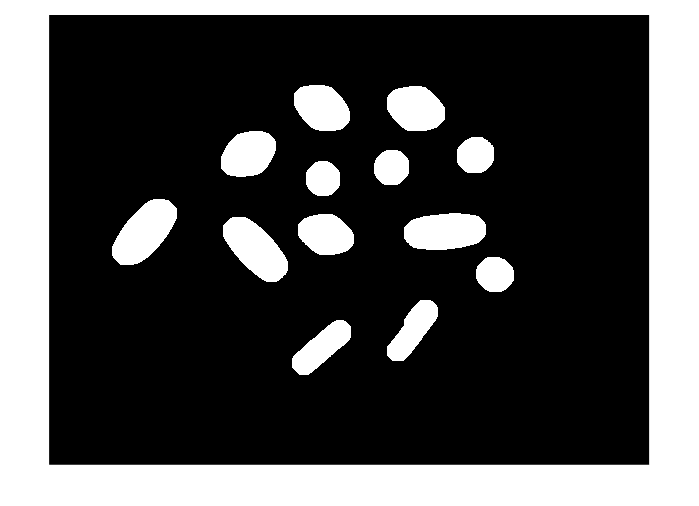

imshow(C3)

%E5=I.*uint8(C3)%相乘就相当于把C3当做遮罩层，把药片抠出来
%imshow(E5)

用APP图像区域分析器

分离出不同面积的药片

紫色药片

%紫色药片
function [BW_out,properties] = filterRegions_1(BW_in)
%filterRegions Filter BW image using auto-generated code from imageRegionAnalyzer app.

% Auto-generated by imageRegionAnalyzer app on 08-May-2025
%---------------------------------------------------------

BW_out = BW_in;

% Filter image based on image properties.
BW_out = bwpropfilt(BW_out,'Area',[100000, 118751]);

% Get properties.
properties = regionprops(BW_out, {'Area', 'Circularity', 'Eccentricity', 'EquivDiameter', 'EulerNumber', 'MajorAxisLength', 'MinorAxisLength', 'Orientation', 'Perimeter'});
end
Q1 = filterRegions_1(C3)

Q1 = 3000×4000 logical 数组
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0  

 [L,num]=bwlabel(Q1);
 %输出对象数量
 disp(['紫色药片的数目',num2str(num)]);

紫色药片的数目3


黄色菱形药片

 function [BW_out,properties] = filterRegions_2(BW_in)
%filterRegions Filter BW image using auto-generated code from imageRegionAnalyzer app.

% Auto-generated by imageRegionAnalyzer app on 08-May-2025
%---------------------------------------------------------

BW_out = BW_in;

% Filter image based on image properties.
BW_out = bwpropfilt(BW_out,'Area',[79000, 100000]);

% Get properties.
properties = regionprops(BW_out, {'Area', 'Circularity', 'Eccentricity', 'EquivDiameter', 'EulerNumber', 'MajorAxisLength', 'MinorAxisLength', 'Orientation', 'Perimeter'});
 end
 Q2= filterRegions_2(C3);
 [L,num2]=bwlabel(Q2);
 %输出对象数量
 disp(['黄色菱形药片的数目',num2str(num2)]);

黄色菱形药片的数目4


白色圆形小药片

 function [BW_out,properties] = filterRegions_3(BW_in)
%filterRegions Filter BW image using auto-generated code from imageRegionAnalyzer app.

% Auto-generated by imageRegionAnalyzer app on 08-May-2025
%---------------------------------------------------------

BW_out = BW_in;

% Filter image based on image properties.
BW_out = bwpropfilt(BW_out,'Area',[43627, 50000]);

% Get properties.
properties = regionprops(BW_out, {'Area', 'Circularity', 'Eccentricity', 'EquivDiameter', 'EulerNumber', 'MajorAxisLength', 'MinorAxisLength', 'Orientation', 'Perimeter'});
 end
 Q3= filterRegions_3(C3);
  [L,num3]=bwlabel(Q3);
 %输出对象数量
 disp(['白色圆形小药片的数目',num2str(num3)]);

白色圆形小药片的数目4


胶囊数目

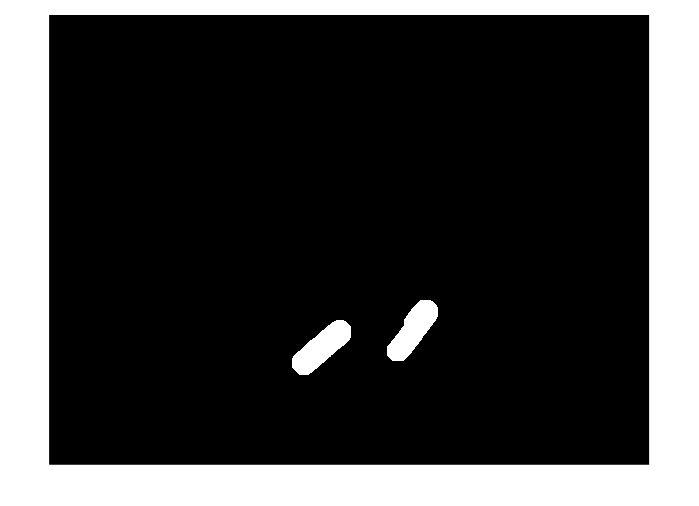

 function [BW_out,properties] = filterRegions_4(BW_in)
%filterRegions Filter BW image using auto-generated code from imageRegionAnalyzer app.

% Auto-generated by imageRegionAnalyzer app on 08-May-2025
%---------------------------------------------------------

BW_out = BW_in;

% Filter image based on image properties.
BW_out = bwpropfilt(BW_out,'Area',[50000, 73000]);

% Get properties.
properties = regionprops(BW_out, {'Area', 'Circularity', 'Eccentricity', 'EquivDiameter', 'EulerNumber', 'MajorAxisLength', 'MinorAxisLength', 'Orientation', 'Perimeter'});
 end
  Q4= filterRegions_4(C3);
  imshow(Q4)

  [L,num4]=bwlabel(Q4);
 %输出对象数量
 disp(['胶囊的数目',num2str(num4)]);

胶囊的数目2
